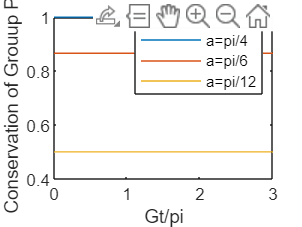

Gt=0:0.01*pi:3*pi;

alpha1=pi/4;
alpha2=pi/6;
alpha3=pi/12;

Con_AB_1=(cos(Gt/2)).^2.*(abs(sin(2*alpha1))-((sin(Gt/2))).^2*cos(alpha1)^2);
Con_AB_2=(cos(Gt/2)).^2.*(abs(sin(2*alpha2))-((sin(Gt/2))).^2*cos(alpha2)^2);
Con_AB_3=(cos(Gt/2)).^2.*(abs(sin(2*alpha3))-((sin(Gt/2))).^2*cos(alpha3)^2);

Con_AB_me_1=(cos(Gt/2)).^2.*(abs(sin(2*alpha1))-2*((sin(Gt/2))).^2*cos(alpha1)^2);
Con_AB_me_2=(cos(Gt/2)).^2.*(abs(sin(2*alpha2))-2*((sin(Gt/2))).^2*cos(alpha2)^2);
Con_AB_me_3=(cos(Gt/2)).^2.*(abs(sin(2*alpha3))-2*((sin(Gt/2))).^2*cos(alpha3)^2);

Con_ab_1=(sin(Gt/2)).^2.*(abs(sin(2*alpha1))-2*((cos(Gt/2))).^2*cos(alpha1)^2); 
Con_ab_2=(sin(Gt/2)).^2.*(abs(sin(2*alpha2))-2*((cos(Gt/2))).^2*cos(alpha2)^2); 
Con_ab_3=(sin(Gt/2)).^2.*(abs(sin(2*alpha3))-2*((cos(Gt/2))).^2*cos(alpha3)^2); 

Con_Ab_1=1/2*(cos(alpha1))^2*abs(sin(Gt)).*(2*abs(tan(alpha1))-abs(sin(Gt)));
Con_Ab_2=1/2*(cos(alpha2))^2*abs(sin(Gt)).*(2*abs(tan(alpha2))-abs(sin(Gt)));
Con_Ab_3=1/2*(cos(alpha3))^2*abs(sin(Gt)).*(2*abs(tan(alpha3))-abs(sin(Gt)));

Con_Aa_1=abs(sin(Gt))*cos(alpha1)^2;
Con_Aa_2=abs(sin(Gt))*cos(alpha2)^2;
Con_Aa_3=abs(sin(Gt))*cos(alpha3)^2;


%For the other partial group with psi
Con2_AB_1=abs(sin(2*alpha1))*(cos(Gt/2)).^2;
Con2_AB_2=abs(sin(2*alpha2))*(cos(Gt/2)).^2;
Con2_AB_3=abs(sin(2*alpha3))*(cos(Gt/2)).^2;

Con2_ab_1=abs(sin(2*alpha1))*(sin(Gt/2)).^2;
Con2_ab_2=abs(sin(2*alpha2))*(sin(Gt/2)).^2;
Con2_ab_3=abs(sin(2*alpha3))*(sin(Gt/2)).^2;

Con2_Ab_1=1/2*abs(sin(2*alpha1))*abs(sin(Gt));
Con2_Ab_2=1/2*abs(sin(2*alpha2))*abs(sin(Gt));
Con2_Ab_3=1/2*abs(sin(2*alpha3))*abs(sin(Gt));

Con2_Aa_1=abs(sin(Gt))*(cos(alpha1))^2;
Con2_Aa_2=abs(sin(Gt))*(cos(alpha2))^2;
Con2_Aa_3=abs(sin(Gt))*(cos(alpha3))^2;

Con2_Bb_1=abs(sin(Gt))*(sin(alpha1))^2;
Con2_Bb_2=abs(sin(Gt))*(sin(alpha2))^2;
Con2_Bb_3=abs(sin(Gt))*(sin(alpha3))^2;

Conservation1=Con_AB_me_1 + Con_ab_1 + 2*Con_Aa_1*abs(tan(alpha1)) - 2*Con_Ab_1;
Conservation2=Con_AB_me_2 + Con_ab_2 + 2*Con_Aa_2*abs(tan(alpha2)) - 2*Con_Ab_2;
Conservation3=Con_AB_me_3 + Con_ab_3 + 2*Con_Aa_3*abs(tan(alpha3)) - 2*Con_Ab_3;

Conservation1_2=Con2_AB_1 +Con2_ab_1+ 2*Con2_Aa_1*abs(tan(alpha1))- 2*Con2_Ab_1;
Conservation2_2=Con2_AB_2 +Con2_ab_2+ 2*Con2_Aa_2*abs(tan(alpha2))- 2*Con2_Ab_2;
Conservation3_2=Con2_AB_3 +Con2_ab_3+ 2*Con2_Aa_3*abs(tan(alpha3))- 2*Con2_Ab_3;

% figure;
% plot(Gt/pi,Con_AB)
% hold on
% plot(Gt/pi,Con_AB_me_1)
% legend('article','my')
% 
% xlabel('Gt/pi');
% ylabel('C_A_B');
% 
% figure;
% plot(Gt/pi,Con_ab_1);
% xlabel('Gt/pi');
% ylabel('C_a_b');
% 
% figure;
% plot(Gt/pi,Con_ab_1);
% hold on;
% plot(Gt/pi,Con_AB_me_1);
% xlabel('Gt/pi');
% ylabel('C_a_b');
% legend('Con_a_b','Con_A_B');
% 
% figure;
% plot(Gt/pi, Con_AB_me_1);
% hold on;
% plot(Gt/pi, Con_AB_me_2);
% plot(Gt/pi, Con_AB_me_3);
% xlabel('Gt/pi');
% ylabel('C_A_B');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% 
% figure;
% plot(Gt/pi, Con_ab_1);
% hold on;
% plot(Gt/pi, Con_ab_2);
% plot(Gt/pi, Con_ab_3);
% xlabel('Gt/pi');
% ylabel('C_a_b');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con_Ab_1);
% hold on;
% plot(Gt/pi, Con_Ab_2);
% plot(Gt/pi, Con_Ab_3);
% xlabel('Gt/pi');
% ylabel('C_A_b');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con_Aa_1);
% hold on;
% plot(Gt/pi, Con_Aa_2);
% plot(Gt/pi, Con_Aa_3);
% xlabel('Gt/pi');
% ylabel('C_A_a');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% %For the other partial trace
% 
% figure;
% plot(Gt/pi, Con2_AB_1);
% hold on;
% plot(Gt/pi, Con2_AB_2);
% plot(Gt/pi, Con2_AB_3);
% xlabel('Gt/pi');
% ylabel('C_A_B');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con2_ab_1);
% hold on;
% plot(Gt/pi, Con2_ab_2);
% plot(Gt/pi, Con2_ab_3);
% xlabel('Gt/pi');
% ylabel('C_a_b');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con2_Ab_1);
% hold on;
% plot(Gt/pi, Con2_Ab_2);
% plot(Gt/pi, Con2_Ab_3);
% xlabel('Gt/pi');
% ylabel('C_A_b');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con2_Aa_1);
% hold on;
% plot(Gt/pi, Con2_Aa_2);
% plot(Gt/pi, Con2_Aa_3);
% xlabel('Gt/pi');
% ylabel('C_A_a');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con2_Bb_1);
% hold on;
% plot(Gt/pi, Con2_Bb_2);
% plot(Gt/pi, Con2_Bb_3);
% xlabel('Gt/pi');
% ylabel('C_B_b');
% legend('a=pi/4','a=pi/6','a=pi/12');
% 
% figure;
% plot(Gt/pi, Con2_AB_1);
% hold on;
% plot(Gt/pi, Con2_ab_1);
% xlabel('Gt/pi');
% ylabel('Concurrence');
% legend('C_A_B','C_a_b');

figure;
plot(Gt/pi, Conservation1);
hold on;
plot(Gt/pi, Conservation2);
plot(Gt/pi, Conservation3);
xlabel('Gt/pi');
ylabel('Conservation of Grouup Phi');
legend('a=pi/4','a=pi/6','a=pi/12');

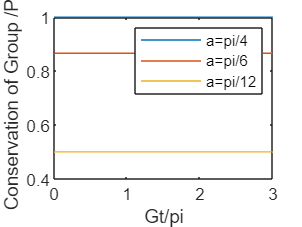


figure;
plot(Gt/pi, Conservation1_2);
hold on;
plot(Gt/pi, Conservation2_2);
plot(Gt/pi, Conservation3_2);
xlabel('Gt/pi');
ylabel('Conservation of Group /Psi');
legend('a=pi/4','a=pi/6','a=pi/12');